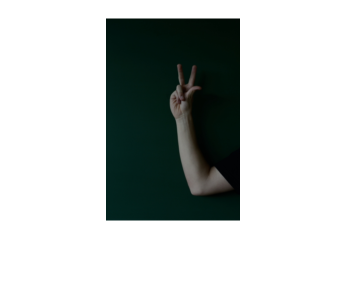

clear all

name = "3_A_hgr2B_id09_1";

% Por cada imagen del directorio de entrenamiento calculamos el histograma
% 2D de de la imagen filtrada con los pixeles que corresponden a la piel.

% Obtenemos el nombre del fichero y calculamos el histigrama 2D de
% las componentes de crominancia de los pixeles de piel de la
% imagen.
img = imread("Dataset_cop/Training-Dataset/Images/" + name + ".jpg");
ideal_mask_path = "Dataset_cop/Training-Dataset/Masks-Ideal/" + name + ".bmp";
ideal_mask = imcomplement(imread(ideal_mask_path));

[width, height, ~] = size(img);
DIEZMADO = 3;
img = imresize(img,[width/DIEZMADO,height/DIEZMADO],'Method','bilinear');
ideal_mask = imresize(ideal_mask,[width/DIEZMADO,height/DIEZMADO],'Method','bilinear');

imshow(img)

[L, a, b] = calc_hist_2D(img, ideal_mask, true);

Histograma completo de la imagen

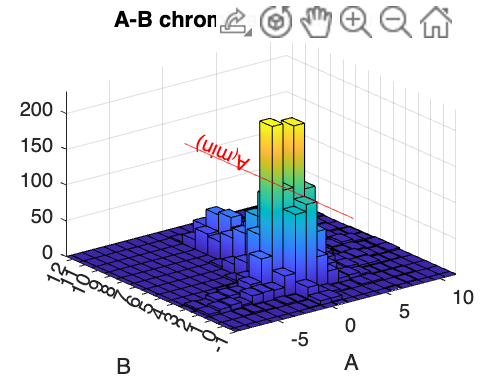

SALTO = 1;
[N_cb,edges_cb] = histcounts(a);
[N_cr,edges_cr] = histcounts(b);

figure
hist3([a, b],{min(edges_cb):SALTO:max(edges_cb) min(edges_cr):SALTO:max(edges_cr)}, 'CdataMode','auto','FaceColor','interp')
title('A-B chrominance histogram'), ylabel('B'), xlabel('A'),
xlim([min(edges_cb) max(edges_cb)])
ylim([min(edges_cr) max(edges_cr)])

xline(1.99,'-r','A_(min)');
xline(23.583,'-r','A_(max)');

yline(-4.617,'-r','B_min');
yline(30.929,'-r','B_max');

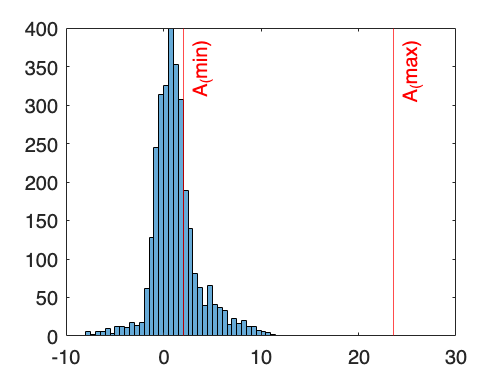


figure()
L_hist = histogram(a);
xline(1.99,'-r','A_(min)');
xline(23.583,'-r','A_(max)');

% xline(13,'-r','L_min');
% xline(70,'-r','L_max');

% plot_2D_hist(a_arr, b_arr);
